# System Identification: Arduino with Black Box Motor as a Plant

### Highlights

- Record the plant with Simulink

- Use black box approach of modeling a plant: System Identification

- Auto-tune the PID controller

### Screenshot of Demo

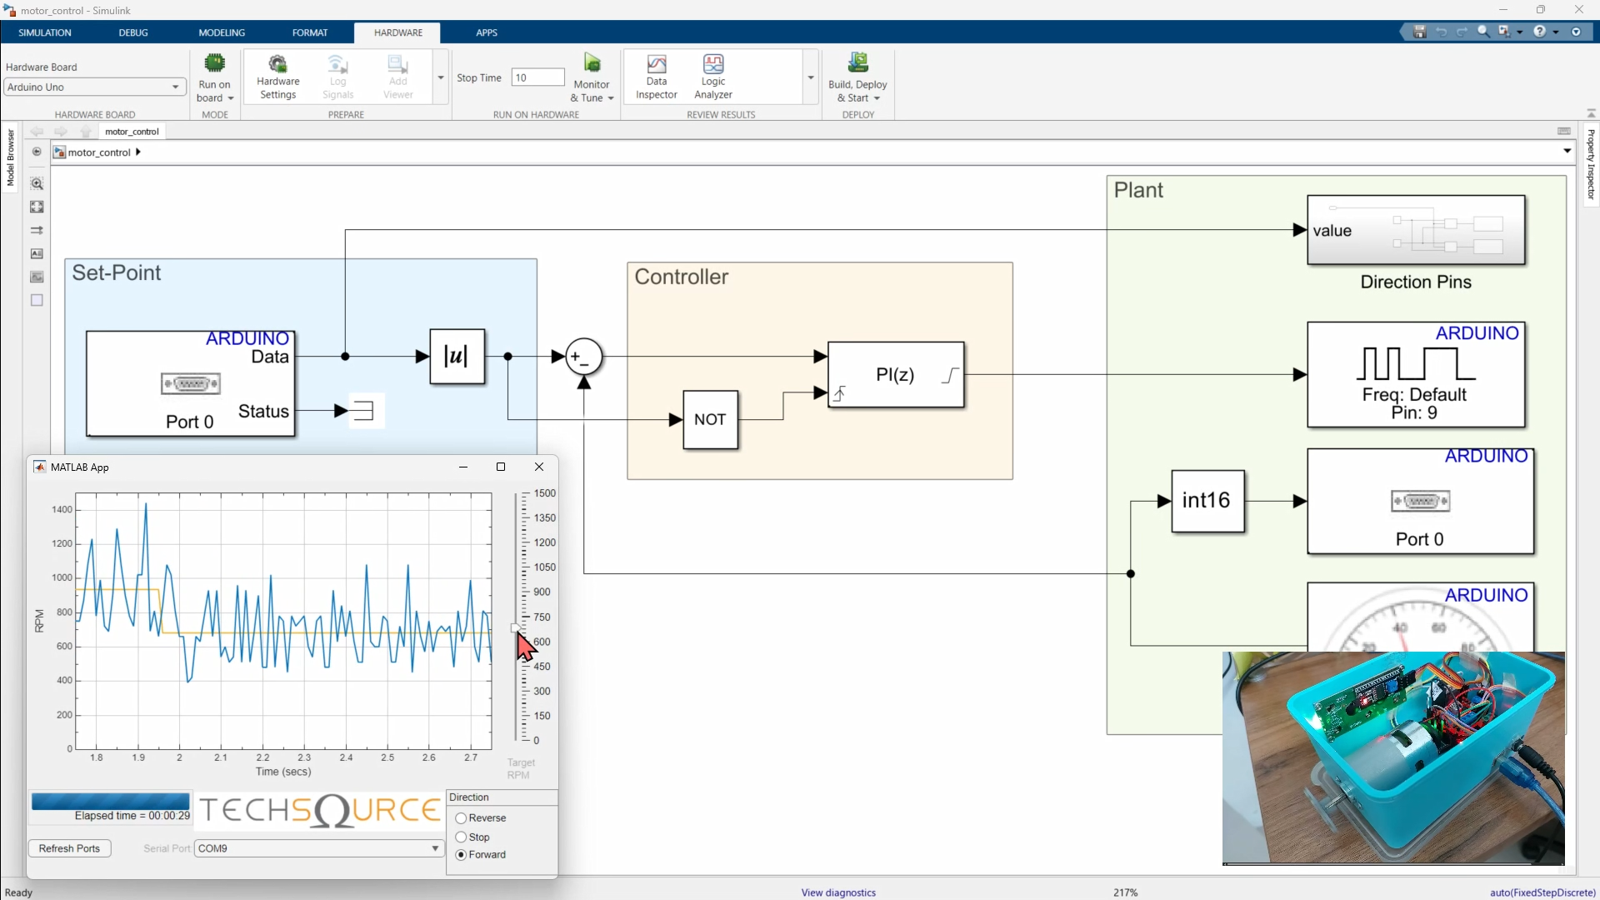

The example is based on Bambang's lunch box.

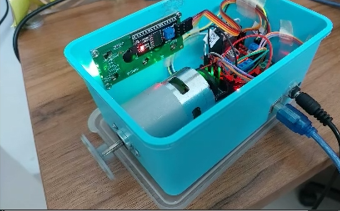

## Hardware Requirements

- [Arduino Uno R3](https://www.digikey.com/en/products/detail/arduino/A000066/2784006)

- [Type-B USB Cable](https://tokopedia.link/Nc4U64hwgSb)

- [L293D](https://www.digikey.com/en/products/detail/stmicroelectronics/L293D/634700)

- [12VDC brushed motor](https://tokopedia.link/gaId8sawgSb) (or similar)

- [12V power supply](https://www.digikey.com/en/products/detail/tri-mag-llc/L6R06H-120/7682617)

- [12V barrel jack power socket](https://www.digikey.com/en/products/detail/lumberg-inc/1610-07/25602821)

## Wiring Diagram

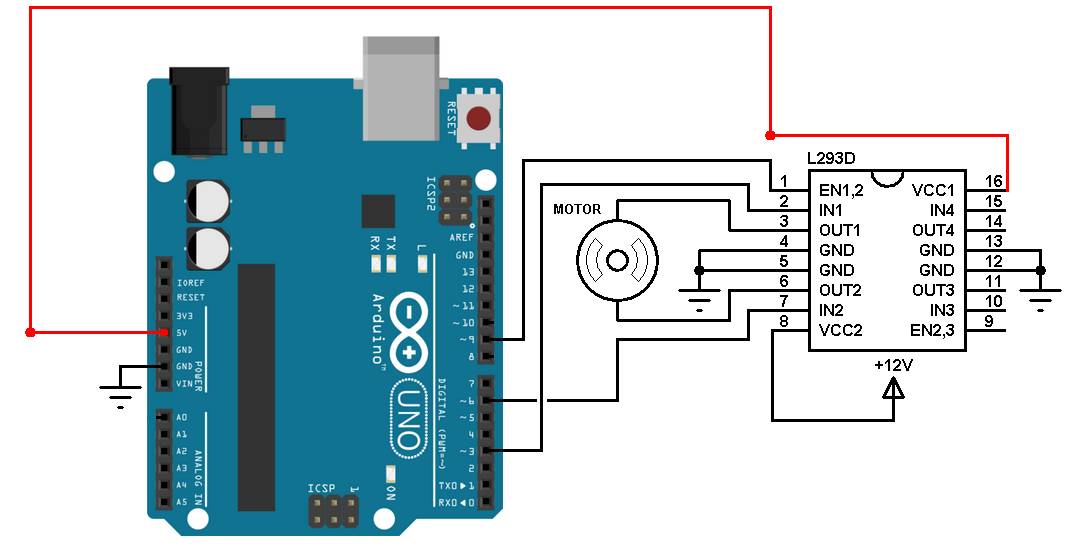

## Toolboxes and Support Packages

- MATLAB

- Simulink

- Stateflow

- System Identification Toolbox

- [Arduino Support Package](https://www.mathworks.com/matlabcentral/fileexchange/47522-matlab-support-package-for-arduino-hardware)

## Content Capability

## Demo Procedure

### (1) Prepare the project

open system_identification_arduino.prj

### (2) Run the physical hardware to record input and output

load_system("record_plant");
set_param("record_plant",SimulationMode="external");

#### For estimation

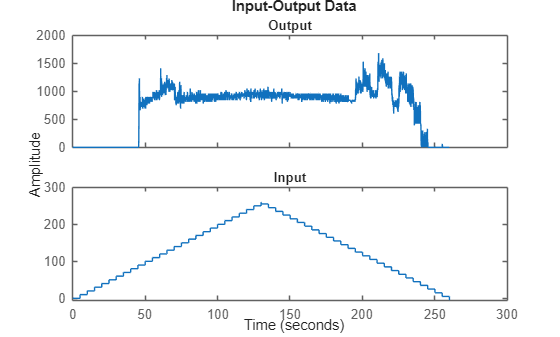

start_recording("record_plant");
estimation_iddata = recording_output(yout);
save('Output\estimation.mat', 'estimation_iddata');
plot(estimation_iddata)

#### For validation

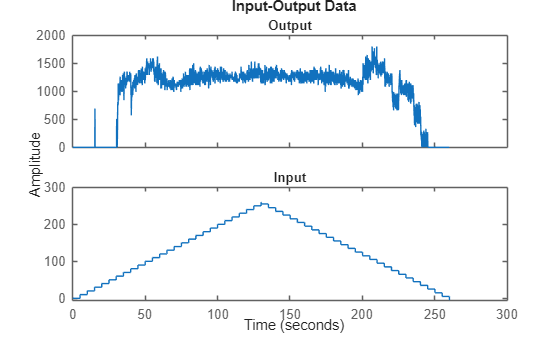

start_recording("record_plant");
validation_iddata = recording_output(yout);
save('Output\validation.mat', 'validation_iddata');
plot(validation_iddata)

### (3) Use System Identification App to estimate plant model

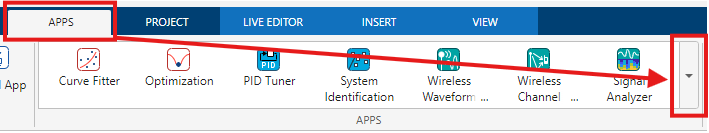

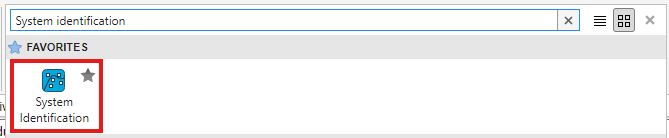

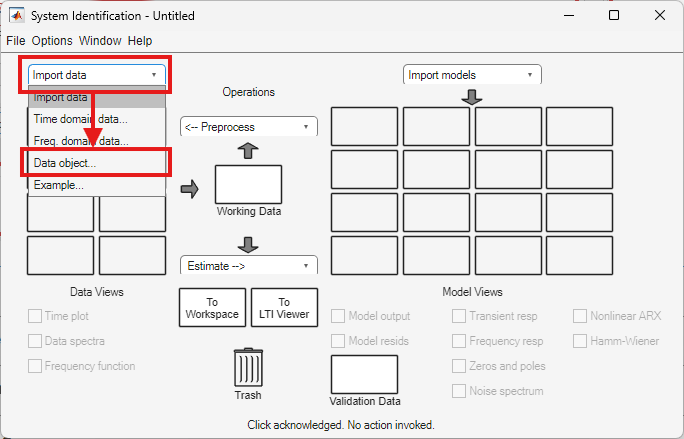

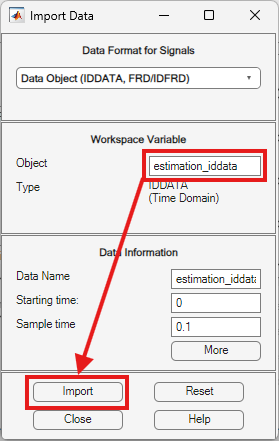

Use these object names and click import for each of them.

- estimation_iddata

- validation_iddata

Then click "Close".

You will see "estimation_idddata" and "validation_iddata" in Data Views. Drag and drop accordingly to this illustration.

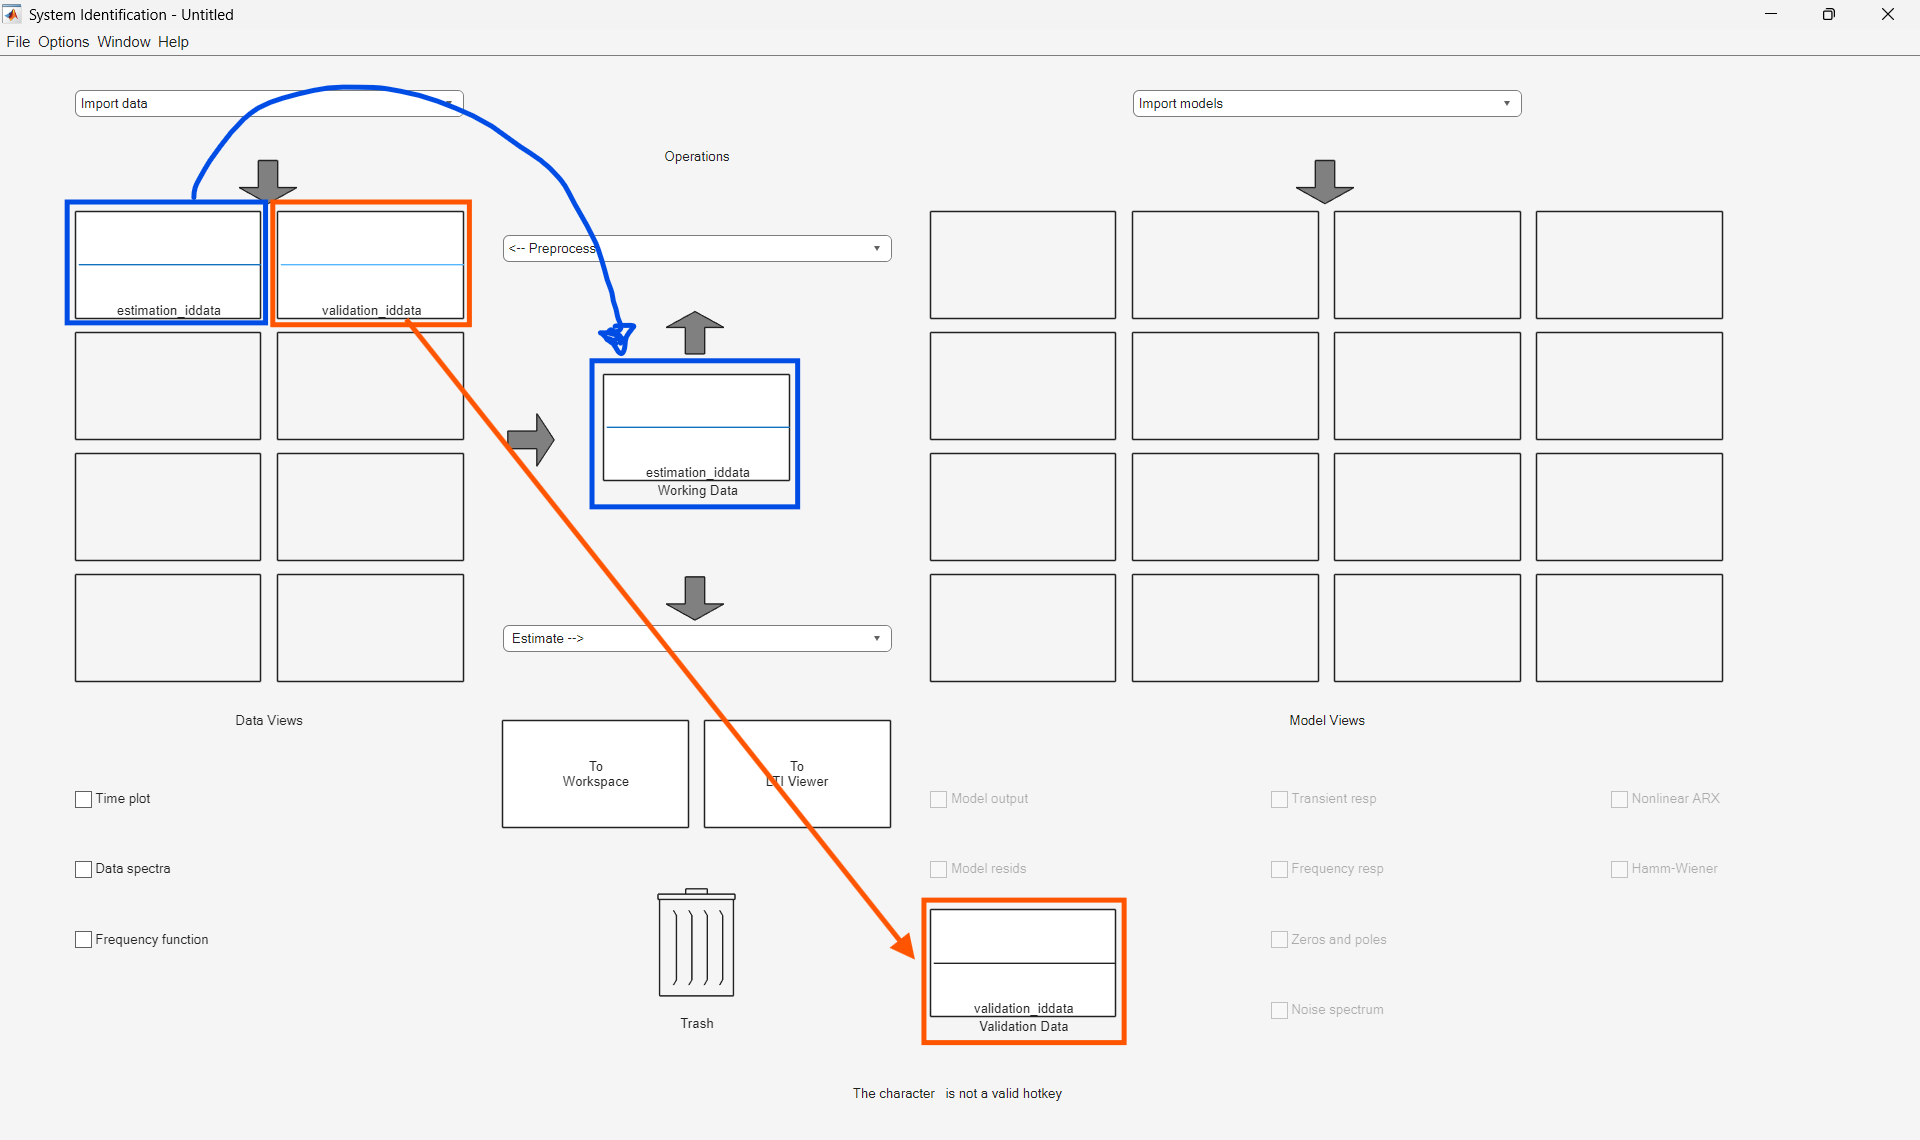

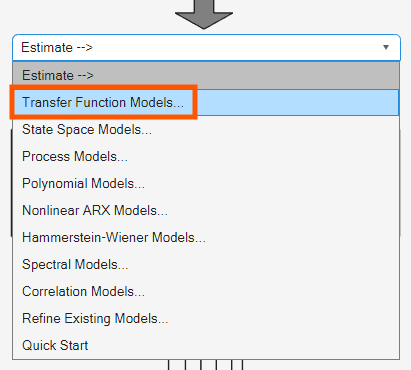

Configure exactly as below. Feel free to modify if you know what you're doing.

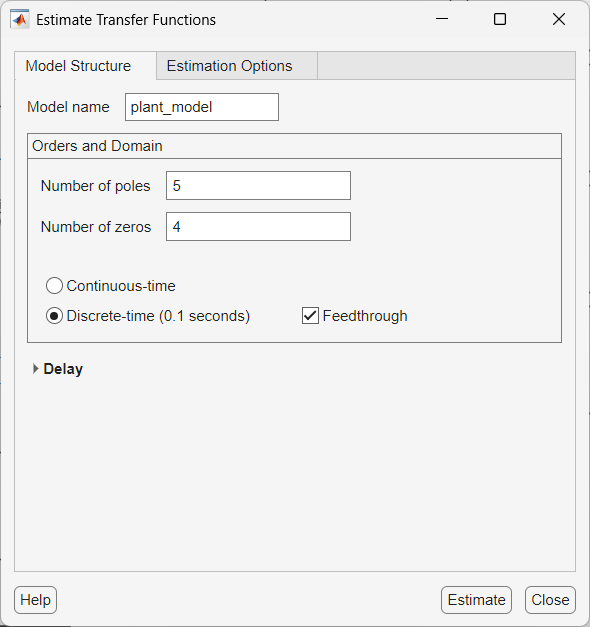

Then click "Estimate" and wait.

Once done, drag the result as below to workspace.

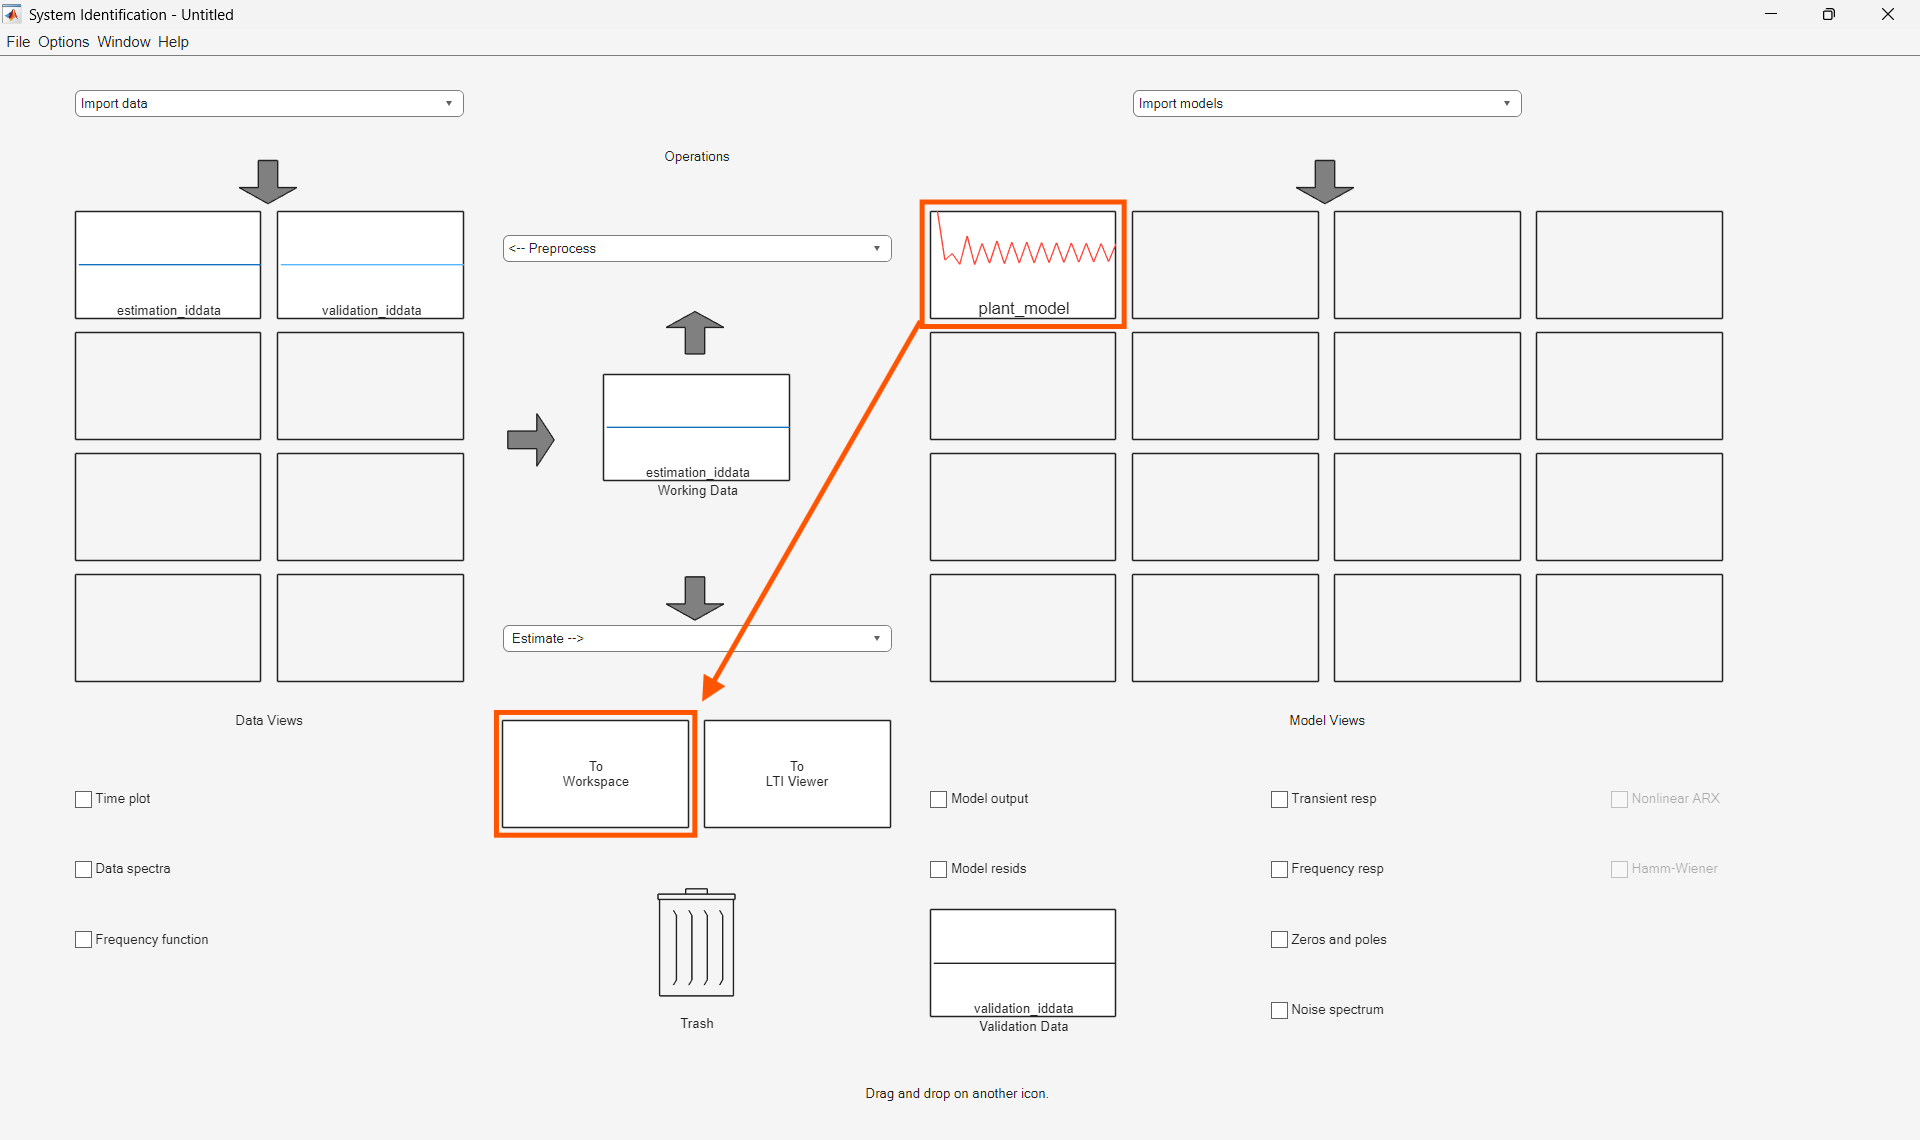

Done! Now you have "plant_model" variable in Workspace, which represents your motor and tachometer as a plant.

**If you want instant result**, here's the custom function:

plant_model = identify_the_plant(estimation_iddata, validation_iddata);

### (4) Simulate and tune

open tune_controller.slx

Double click the PID block

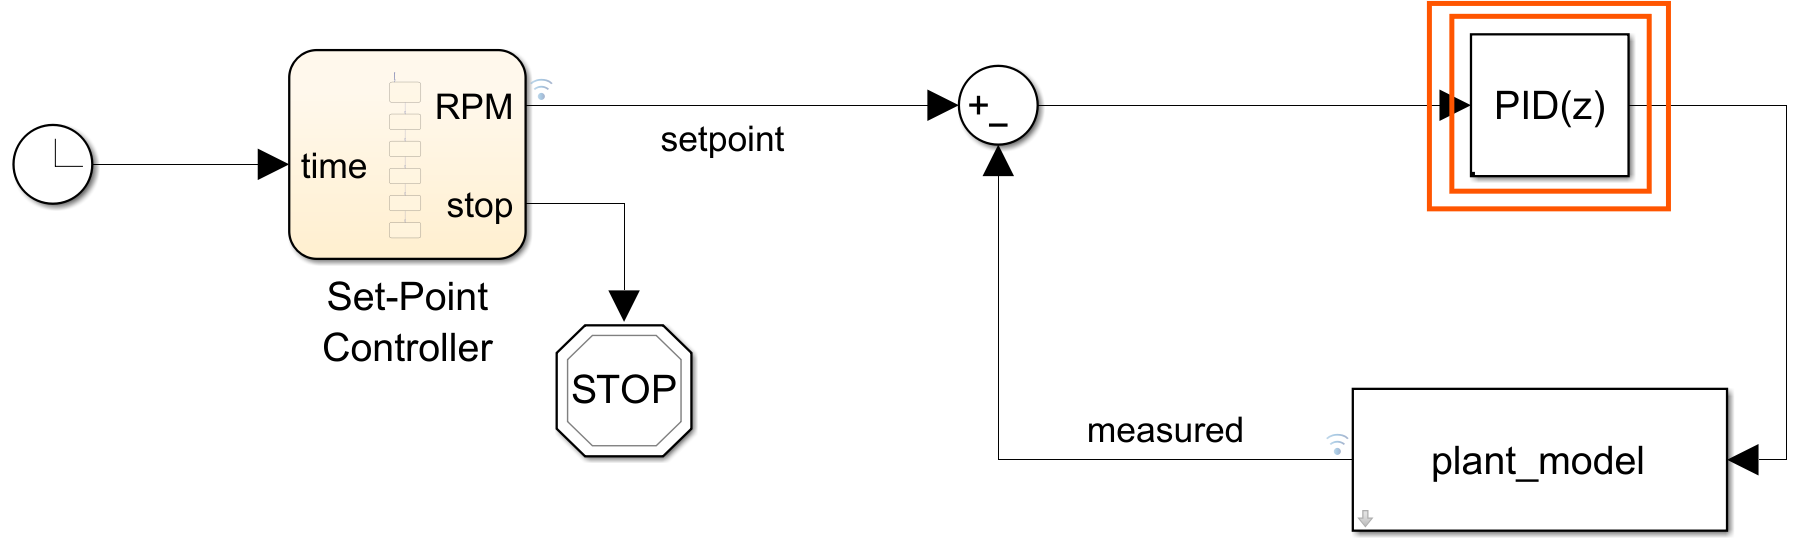

Make sure changes applied and tuning method is "Transfer Function Based", then click Tune button

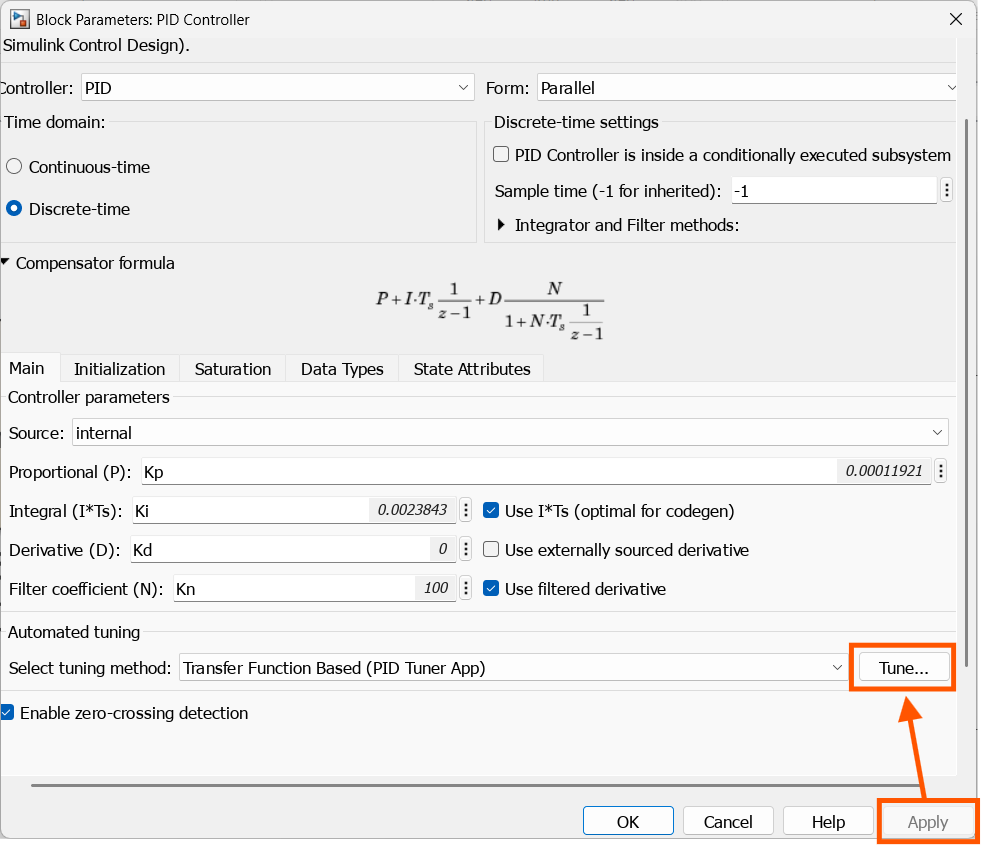

Adjust these sliders below then hit "Update Block" button.

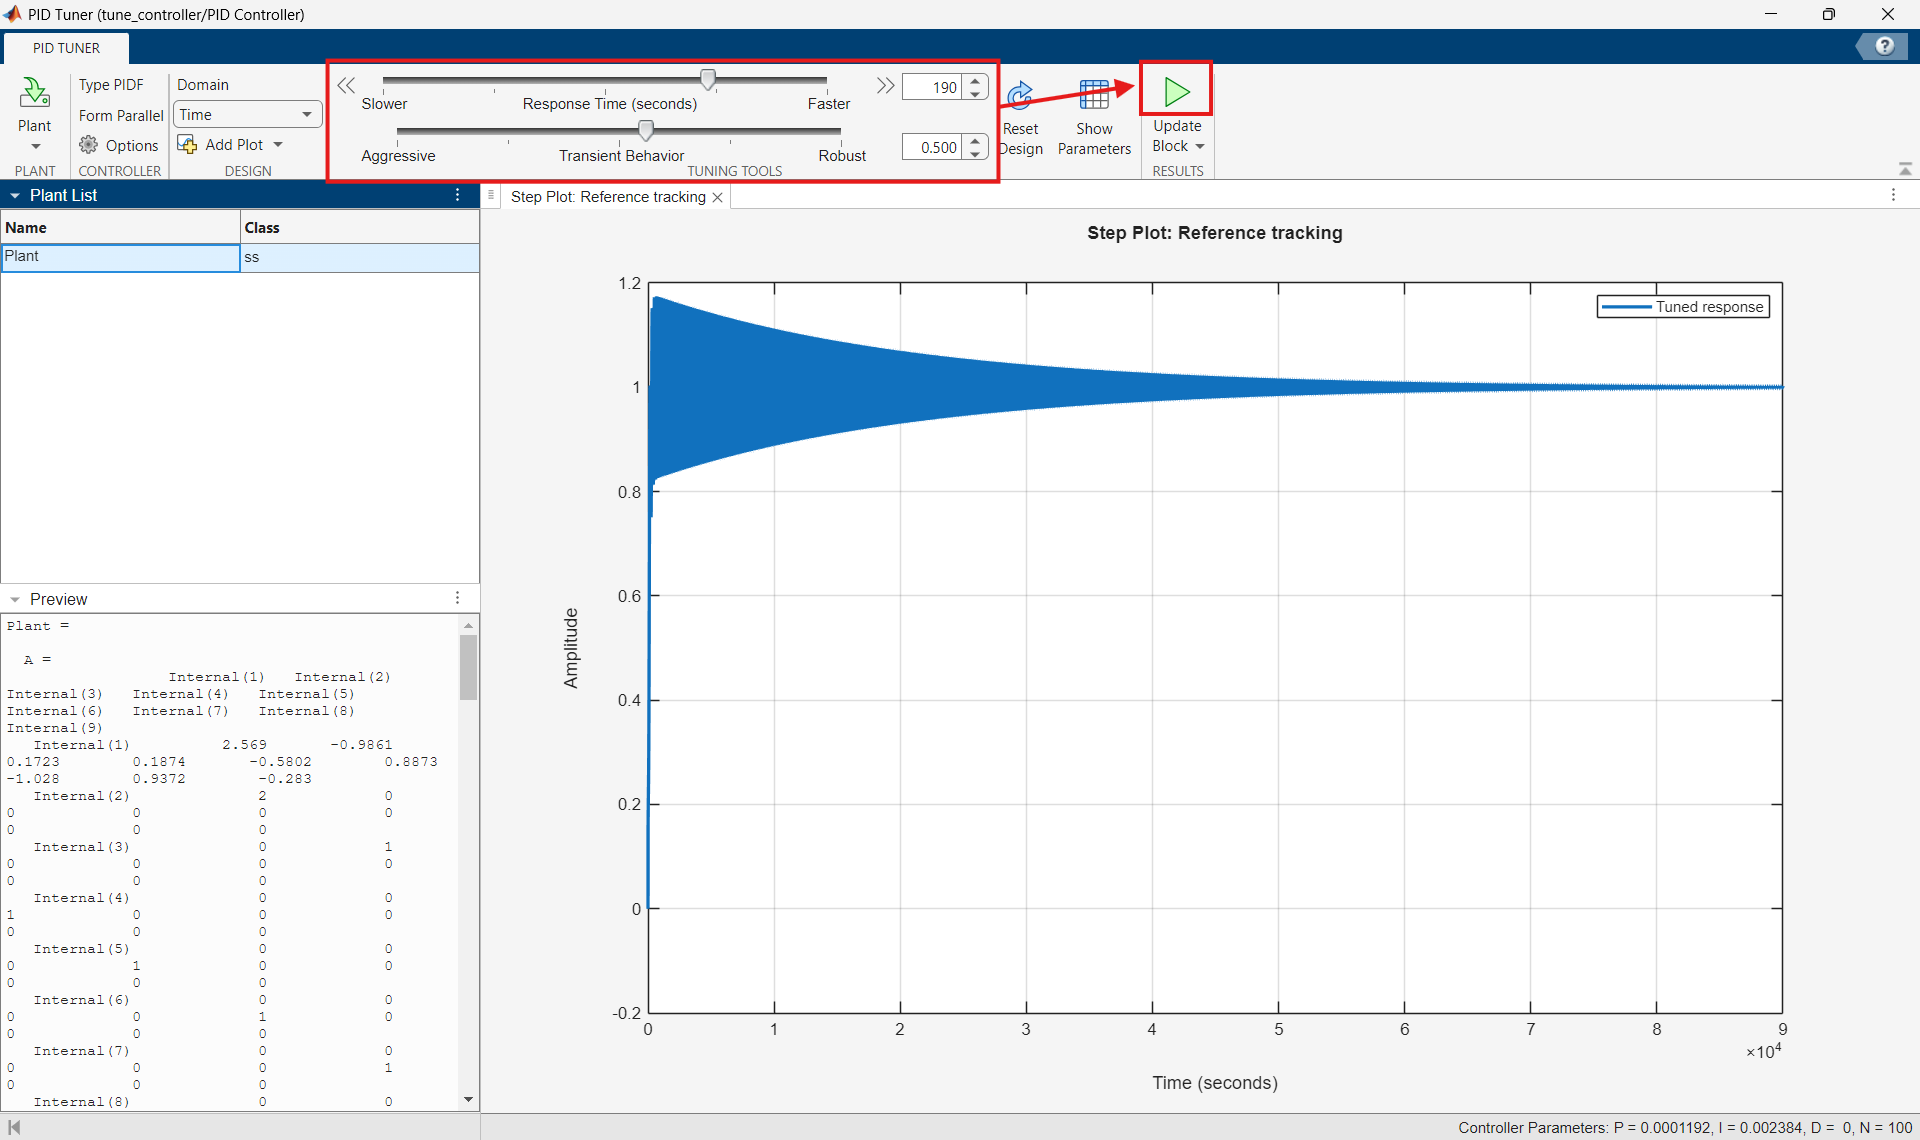

Click OK on Block Parameter dialog. Your PID parameters (Kp, Ki, Kd, and Kn) are now synced to other models via "Data\tuning_parameters.sldd".

**For instant result**, run this custom script:

### (5) Test with the hardware

open hardware_in_the_loop.slx

## References

- [Get Started with System Identification Toolbox](https://www.mathworks.com/help/ident/getting-started-1.html)